# Jacobians: Velocity Relationships

## Introduction

In the last chapter we discussed the relationship between joint coordinates and

end-effector pose – the manipulator kinematics . Now we investigate the relationship

between the rate of change of these quantities – between joint velocity and

velocity of the end-effector . This is called the velocity or differential kinematics of the manipulator.

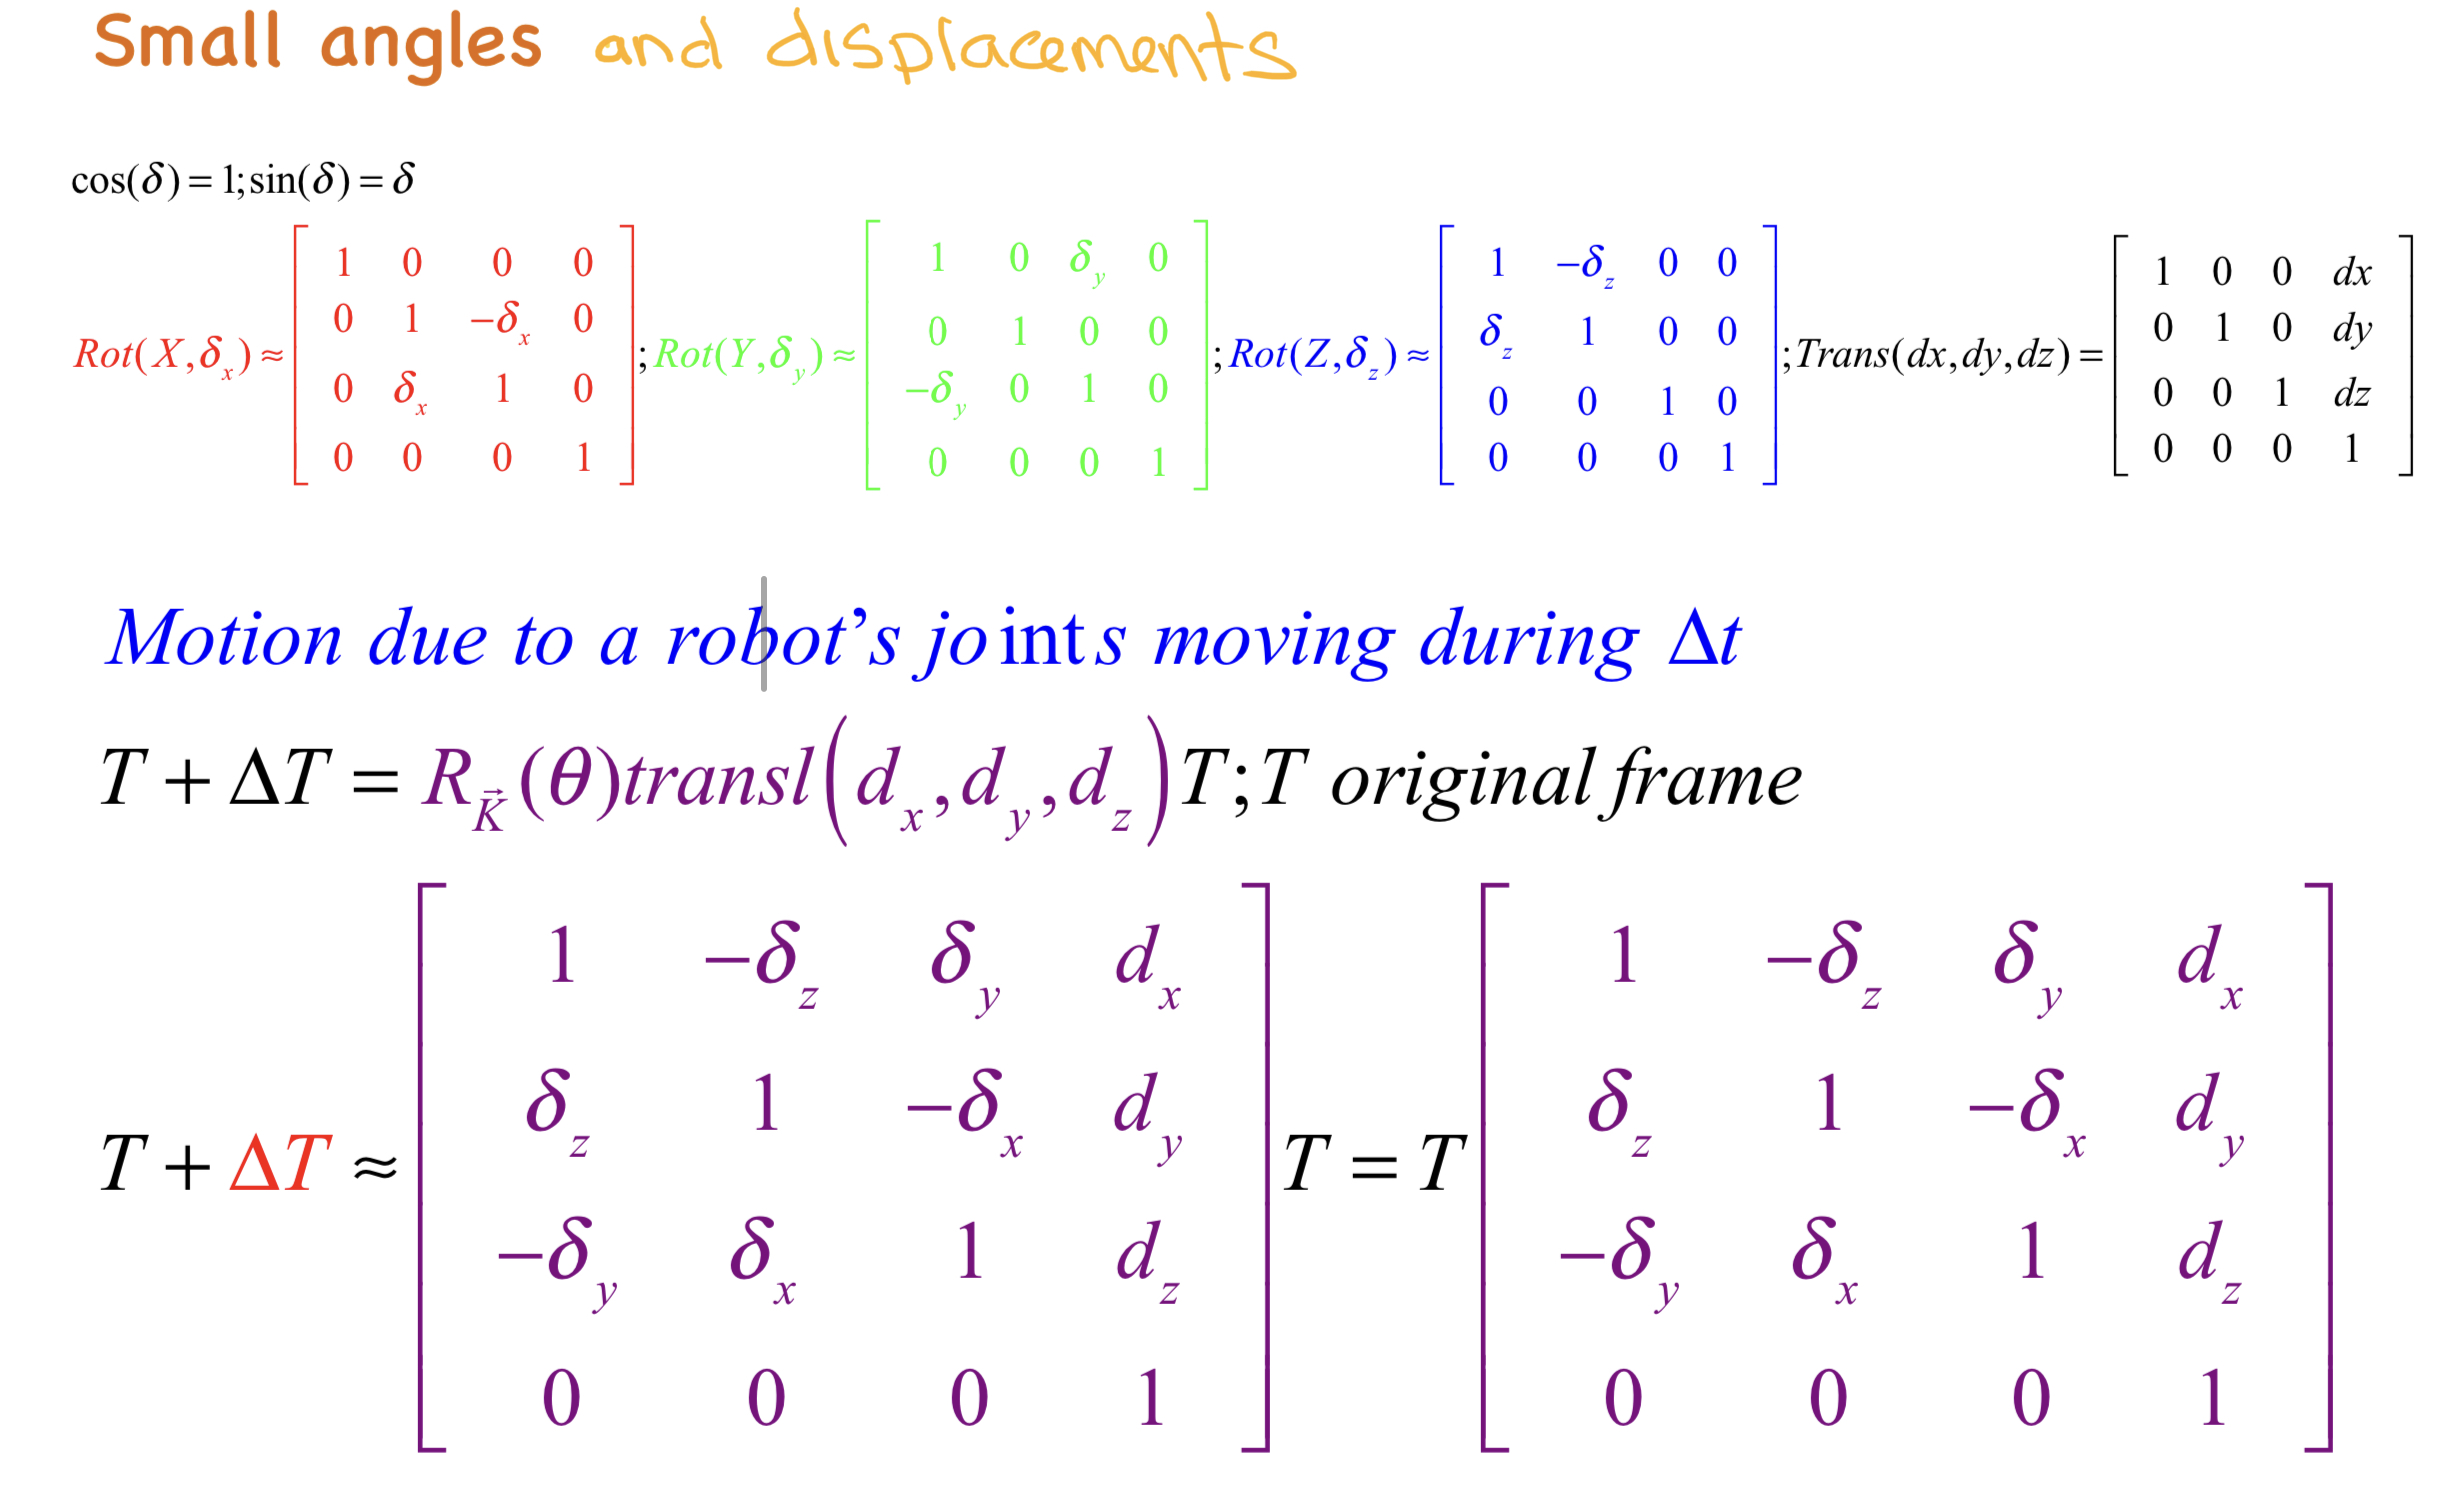

close all
bdclose('all')
clear
clc

## Differential motion

syms delta_x delta_y delta_z dx dy dz
Rx=[1 0 0 0;0 1 -delta_x 0;0 delta_x 1 0; 0 0 0 1]

$$Rx = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & -\delta_{x} & 0\\ 0 & \delta_{x} & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ry=[1 0 delta_y 0;0 1 0 0; -delta_y 0 1 0;0 0 0 1]

$$Ry = \left(\begin{array}{cccc} 1 & 0 & \delta_{y} & 0\\ 0 & 1 & 0 & 0\\ -\delta_{y} & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Rz=[1 -delta_z 0 0; delta_z 1 0 0;0 0 1 0; 0 0 0 1]

$$Rz = \left(\begin{array}{cccc} 1 & -\delta_{z} & 0 & 0\\ \delta_{z} & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T=[1 0 0 dx;0 1 0 dy; 0 0 1 dz; 0 0 0 1]

$$T = \left(\begin{array}{cccc} 1 & 0 & 0 & \mathrm{dx}\\ 0 & 1 & 0 & \mathrm{dy}\\ 0 & 0 & 1 & \mathrm{dz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_dT=T*Rx*Ry*Rz

$$T\_dT = \left(\begin{array}{cccc} 1 & -\delta_{z} & \delta_{y} & \mathrm{dx}\\ \delta_{z}+\delta_{x}\,\delta_{y} & 1-\delta_{x}\,\delta_{y}\,\delta_{z} & -\delta_{x} & \mathrm{dy}\\ \delta_{x}\,\delta_{z}-\delta_{y} & \delta_{x}+\delta_{y}\,\delta_{z} & 1 & \mathrm{dz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_dT=Rx*Ry*Rz*T

$$T\_dT = \left(\begin{array}{cccc} 1 & -\delta_{z} & \delta_{y} & \mathrm{dx}-\delta_{z}\,\mathrm{dy}+\delta_{y}\,\mathrm{dz}\\ \delta_{z}+\delta_{x}\,\delta_{y} & 1-\delta_{x}\,\delta_{y}\,\delta_{z} & -\delta_{x} & \mathrm{dx}\,\left(\delta_{z}+\delta_{x}\,\delta_{y}\right)-\delta_{x}\,\mathrm{dz}-\mathrm{dy}\,\left(\delta_{x}\,\delta_{y}\,\delta_{z}-1\right)\\ \delta_{x}\,\delta_{z}-\delta_{y} & \delta_{x}+\delta_{y}\,\delta_{z} & 1 & \mathrm{dz}-\mathrm{dx}\,\left(\delta_{y}-\delta_{x}\,\delta_{z}\right)+\mathrm{dy}\,\left(\delta_{x}+\delta_{y}\,\delta_{z}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

In both cases if $\delta_{\textrm{xyz}} \&d_{\textrm{xyz}} \approx 0-$


$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCG4uz3bqee0evGueE0jxyaiba
% ieYtf9irVeeu0dXdf9qqqj-lHeeu0xXdbba9frFj0-OqFfea0dXdd9
% vqaq-JfrVkFHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0d
% c9GqpWqabeaabiGaciaacaqabeaadaqaaqaaaOqaaiaadsfacqGHRa
% Wkqaa6daaaaaWdbiabfs5aejaadsfapaGaeyisISleaeFaaaq8b8Ga
% daWadaqaauaadeqaeqaaaaaabaGaaGymaaqaaiabgkHiTiabes7aKn
% aaBaaaleaacaWG6baabeaaaOqaaiabes7aKnaaBaaaleaacaWG5baa
% beaaaOqaaiaadsgadaWgaaWcbaGaamiEaaqabaaakeaacqaH0oazda
% WgaaWcbaGaamOEaaqabaaakeaacaaIXaaabaGaeyOeI0IaeqiTdq2a
% aSbaaSqaaiaadIhaaeqaaaGcbaGaamizamaaBaaaleaacaWG5baabe
% aaaOqaaiabgkHiTiabes7aKnaaBaaaleaacaWG5baabeaaaOqaaiab
% es7aKnaaBaaaleaacaWG4baabeaaaOqaaiaaigdaaeaacaWGKbWaaS
% baaSqaaiaadQhaaeqaaaGcbaGaaGimaaqaaiaaicdaaeaacaaIWaaa
% baGaaGymaaaaaiaawUfacaGLDbaapaGaamivaaaa!5DBC!
\[T + \Delta T \approx \left[ {\begin{array}{*{20}{c}}
  1&{ - {\delta _z}}&{{\delta _y}}&{{d_x}} \\ 
  {{\delta _z}}&1&{ - {\delta _x}}&{{d_y}} \\ 
  { - {\delta _y}}&{{\delta _x}}&1&{{d_z}} \\ 
  0&0&0&1 
\end{array}} \right]T\]$$


## Twolink. Jacobian


$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaamaalaaabaGaeqiTdqMaamiC
% aaqaaiabes7aKjabeI7aXbaacqGH9aqpcaWGkbGaaiikaiabeI7aXj
% aacMcacqGHsgIRcqaH0oazcaWGWbGaeyypa0JaamOsaiaacIcacqaH
% 4oqCcaGGPaGaeqiTdqMaeqiUdeNaeyOKH46aaSaaaeaacqaH0oazca
% WGWbaabaGaeqiTdqMaamiDaaaacqGH9aqpcaWGkbGaaiikaiabeI7a
% XjaacMcadaWcaaqaaiabes7aKjabeI7aXbqaaiabes7aKjaadshaaa
% GaeyOKH4QabmiCayaacaGaeyypa0JaamOsaiaacIcacqaH4oqCcaGG
% PaGafqiUdeNbaiaacqGHsgIRdaahbaWcbeqaaiaaicdaaaGccqaHfp
% qDcqGH9aqpdaahbaWcbeqaaiaaicdaaaGccaWGkbGaaiikaiabeI7a
% XjaacMcacuaH4oqCgaGaaaaa!7C2C!
\[\frac{{\delta p}}{{\delta \theta }} = J(\theta ) \to \delta p = J(\theta )\delta \theta  \to \frac{{\delta p}}{{\delta t}} = J(\theta )\frac{{\delta \theta }}{{\delta t}} \to \dot p = J(\theta )\dot \theta  \to {}^0\upsilon  = {}^0J(\theta )\dot \theta \]$$


The Jacobian computed by the method jacob0 maps joint velocity to the endeffector spatial velocity expressed in the world coordinate frame.

We illustrate the basics with  2-dimensional example using a TwoLink manipulator

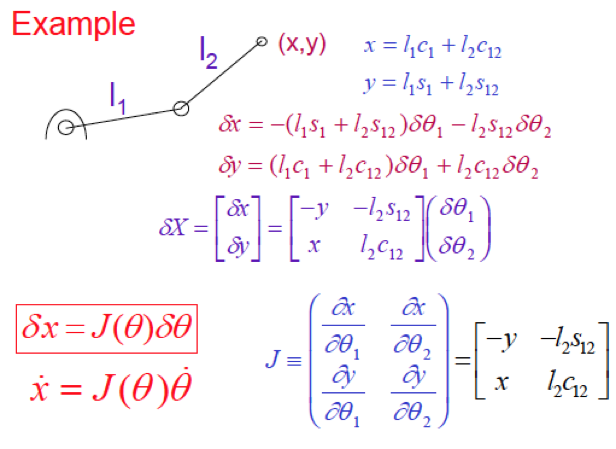

The Jacobian J computed and maps joint velocity to the end effector spatial velocity expressed in the world coordinate  frame.

mdl_planar2_sym
p2

 
p2 = 
 
two link:: 2 axis, RR, stdDH, slowRNE, Symbolic                  
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         a1|          0|          0|
|  2|         q2|          0|         a2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



syms theta_1 theta_2 real

TE = p2.fkine( [theta_1 theta_2] );

p = TE.t; p = p(1:2)

$$p = \left(\begin{array}{c} a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)\\ a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right) \end{array}\right)$$


J = jacobian(p, [theta_1 theta_2]);
J=simplify(J)

$$J = \left(\begin{array}{cc} -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-a_{1}\,\sin\left(\theta_{1}\right) & -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right) & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}\right)$$

Remember

p

$$p = \left(\begin{array}{c} a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)\\ a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right) \end{array}\right)$$


$$\[{}^0{J_{EE}}(\theta ) = \left[ {\begin{array}{*{20}{c}}
  { - y}&{ - {L_2}{s_{12}}} \\ 
  x&{{L_2}{c_{12}}} 
\end{array}} \right]\]$$


### Changing Jacobian’s Reference Frames


$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCG4uz3bqee0evGueE0jxyaiba
% ieYlf9irVeeu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9
% vqaq-JfrVkFHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0d
% c9GqpWqabeaabiGaciaacaqabeaadaqaaqaaaOqaaabaOpaaaG+ape
% WaaWraaSqabeaacaWGbbaaaOGaamOsamaabmaabaGaeqiUdehacaGL
% OaGaayzkaaGaeyypa0ZdamaadmaabaqbamqabiGaaaqaamaaDeaale
% aacaWGcbaabaGaamyqaaaakiaadkfaaeaacaaIWaWaaSbaaSqaaiaa
% iodacaWG4bGaaG4maaqabaaakeaacaaIWaWaaSbaaSqaaiaaiodaca
% WG4bGaaG4maaqabaaakeaadaqhbaWcbaGaamOqaaqaaiaadgeaaaGc
% caWGsbaaaaGaay5waiaaw2faa8qadaahbaWcbeqaaiaadkeaaaGcca
% WGkbWaaeWaaeaacqaH4oqCaiaawIcacaGLPaaacqGHsgIRdaahbaWc
% beqaaiaadkeaaaGccaWGkbWaaeWaaeaacqaH4oqCaiaawIcacaGLPa
% aacqGH9aqppaWaamWaaeaafaWabeGacaaabaWaa0raaSqaaiaadkea
% aeaacaWGbbaaaOGaamOuaaqaaiaaicdadaWgaaWcbaGaaG4maiaadI
% hacaaIZaaabeaaaOqaaiaaicdadaWgaaWcbaGaaG4maiaadIhacaaI
% ZaaabeaaaOqaamaaDeaaleaacaWGcbaabaGaamyqaaaakiaadkfaaa
% aacaGLBbGaayzxaaWaaWbaaSqabeaacqGHsislcaaIXaaaaOWdbmaa
% CeaaleqabaGaamyqaaaakiaadQeadaqadaqaaiabeI7aXbGaayjkai
% aawMcaaaaa!6B1C!
\[{}^AJ\left( \theta  \right) = \left[ {\begin{array}{*{20}{c}}
  {{}_B^AR}&{{0_{3x3}}} \\ 
  {{0_{3x3}}}&{{}_B^AR} 
\end{array}} \right]{}^BJ\left( \theta  \right) \to {}^BJ\left( \theta  \right) = {\left[ {\begin{array}{*{20}{c}}
  {{}_B^AR}&{{0_{3x3}}} \\ 
  {{0_{3x3}}}&{{}_B^AR} 
\end{array}} \right]^{ - 1}}{}^AJ\left( \theta  \right)\]$$



$$\[{}^1J\left( \theta  \right) = {}_1^0{R^T}{}^0J\left( \theta  \right) = \left[ {\begin{array}{*{20}{c}}
  { - {L_2}{s_2}}&{ - {L_2}{s_2}} \\ 
  {{L_1} + {L_2}{c_2}}&{{L_2}{c_2}} 
\end{array}} \right]\]$$


J_1=rot2(-theta_1)*J

$$J\_1 = \begin{array}{l} \left(\begin{array}{cc} \sin\left(\theta_{1}\right)\,\sigma_{2}-\cos\left(\theta_{1}\right)\,\sigma_{1} & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{1}\right)-a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\,\sigma_{2}+\sin\left(\theta_{1}\right)\,\sigma_{1} & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{1}\right)+a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)\\ \sigma_{2}=a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

J_1=simplify(J_1)

$$J\_1 = \left(\begin{array}{cc} -a_{2}\,\sin\left(\theta_{2}\right) & -a_{2}\,\sin\left(\theta_{2}\right)\\ a_{1}+a_{2}\,\cos\left(\theta_{2}\right) & a_{2}\,\cos\left(\theta_{2}\right) \end{array}\right)$$

## 6R Robot. Jacobian

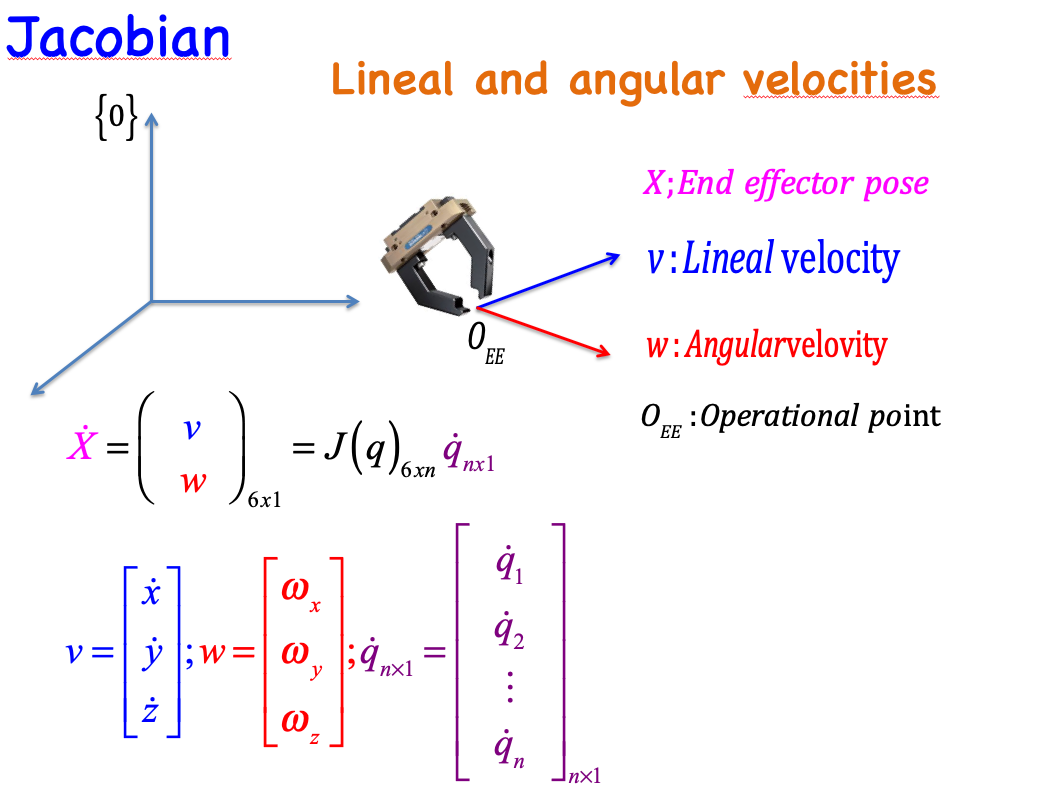

$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaamaaCeaaleqabaGaaGimaaaa
% kiabew8a1jabg2da9maadmaabaqbaeqabeGbaaaabaGabmiEayaaca
% aabaGabmyEayaacaaabaGabmOEayaacaaabaGaam4DamaaBaaaleaa
% caWG4baabeaaaOqaaiaadEhadaWgaaWcbaGaamyEaaqabaaakeaaca
% WG3bWaaSbaaSqaaiaadQhaaeqaaaaaaOGaay5waiaaw2faamaaCaaa
% leqabaGaamivaaaakiabgIGiolabgYricpaaCaaaleqabaGaaGOnaa
% aaaaa!5109!
\[{}^0\upsilon  = {\left[ {\begin{array}{*{20}{c}}
  {\dot x}&{\dot y}&{\dot z}&{{w_x}}&{{w_y}}&{{w_z}} 
\end{array}} \right]^T} \in {\Re ^6}\]$ and $% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaamaaCeaaleqabaGaaGimaaaa
% kiaadQeacaGGOaGaeqiUdeNaaiykaiabgIGiolabgYricpaaCaaale
% qabaGaaGOnaiabgEna0kaad6eaaaaaaa!4848!
\[{}^0J(\theta ) \in {\Re ^{6 \times N}}\]$

For a realistic 3-dimensional robot this Jacobian matrix can be numerically computed by the 'jacob0'  method of the SerialLink object, based on its Denavit-Hartenberg parameters. For the Puma robot in  the pose shown in the nex figure, 

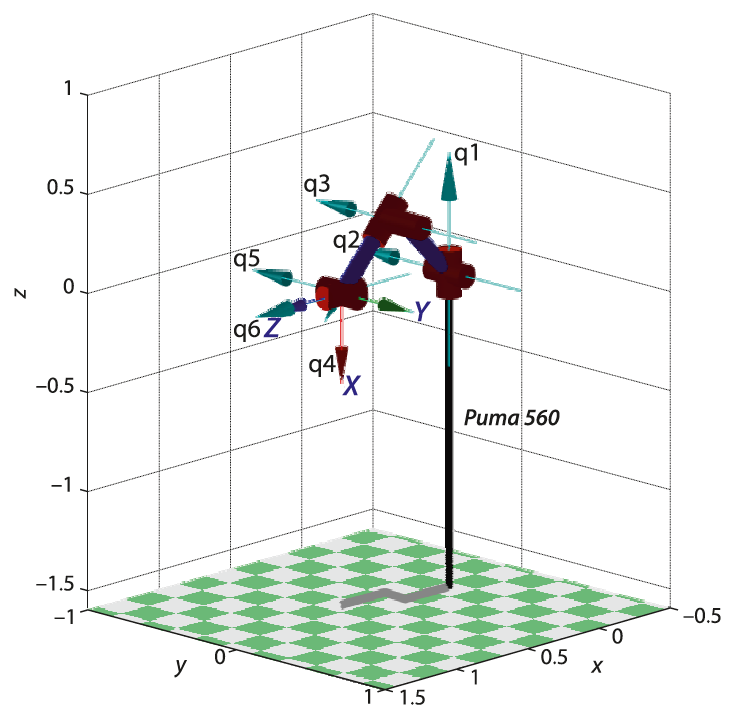

The Jacobian is  

mdl_puma560
J = p560.jacob0(qn)

J =     0.1501    0.0144    0.3197         0         0         0
    0.5963    0.0000    0.0000         0         0         0
    0.0000    0.5963    0.2910         0         0         0
         0   -0.0000   -0.0000    0.7071   -0.0000    1.0000
    0.0000   -1.0000   -1.0000   -0.0000   -1.0000   -0.0000
    1.0000    0.0000    0.0000   -0.7071    0.0000   -0.0000


Making Jacobian by hand

T=p560.fkine(qn)

 

T = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


T_1=p560.fkine(qn+[0.000001 0 0 0 0 0])% small change in theta_1

 

T_1 = 
         0   -0.0000    1.0000    0.5963
         0    1.0000    0.0000     -0.15
        -1         0         0  -0.01435
         0         0         0         1


J13=(T_1.transl-T.transl)/0.000001 % must be the slope = (J(1:3,1))

J13 =     0.1500    0.5963         0


### Jacobian in end-effector

To obtain the spatial velocity in the end-effector coordinate frame we introduce the velocity transformation  from the world frame to the end-effector frame which is a function of the end-effector pose


$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCG4uz3bqee0evGueE0jxyaiba
% ieYlf9irVeeu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9
% vqaq-JfrVkFHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0d
% c9GqpWqabeaabiGaciaacaqabeaadaqaaqaaaOqaaabaaaaaaaaape
% WaaWraaSqabeaacaaIWaaaaOGaeqyXdu3daiabg2da9maadmaabaqb
% amqabiqaaaqaamaaCeaaleqabaGaaGimaaaakabaaaaaaG+apiGaam
% ODaaWdaeaadaahbaWcbeqaaiaaicdaaaGcqaa6daaaaaWddiaadEha
% aaaapaGaay5waiaaw2faaiabg2da9maayaaaqaa6daaaOpWdeeaada
% ahbaWcbeqaaiaaicdaaaGccaWGkbWaaeWaaeaacqaH4oqCaiaawIca
% caGLPaaaaSWdaeaacaWGbbGaamiDaiaaysW7caWGfbGaamyraiaays
% W7caWGWbGaam4BaiaadohacaWGLbaakiaawIJ-aiqbeI7aXzaacaGa
% ai4oaiaadshacaWGObGaamyzaiaaysW7caWGYbGaamyzaiaadohaca
% WG1bGaamiBaiaadshacaWGPbGaamOBaiaadEgapeWaaWraaSqabeaa
% caaIWaaaaOGaeqyXdu3daiaaysW7caWG3bGaamyAaiaadYgacaWGSb
% GaaGjbVlaadkgacaWGLbGaaGjbVlaadMgacaWGUbWaaiWaaeaacaaI
% WaaacaGL7bGaayzFaaaaaa!745E!
\[{}^0\upsilon  = \left[ {\begin{array}{*{20}{c}}
  {{}^0v} \\ 
  {{}^0w} 
\end{array}} \right] = \underbrace {{}^0J\left( \theta  \right)}_{}\dot \theta ;the\;resulting{}^0\upsilon \;will\;be\;in\left\{ 0 \right\}\]$$



$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCG4uz3bqee0evGueE0jxyaiba
% ieYlf9irVeeu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9
% vqaq-JfrVkFHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0d
% c9GqpWqabeaabiGaciaacaqabeaadaqaaqaaaOqaaabaaaaaaaaape
% WaaWraaSqabeaacaWGcbaaaOGaeqyXdu3daiabg2da9maadmaabaqb
% amqabiqaaaqaamaaCeaaleqabaGaamOqaaaakabaaaaaaG+apiGaam
% ODaaWdaeaadaahbaWcbeqaaiaadkeaaaGcqaa6daaaaaWddiaadEha
% aaaapaGaay5waiaaw2faaiabg2da9maayaaaqaa6daaaOpWdeeaada
% ahbaWcbeqaaiaadkeaaaGccaWGkbWaaeWaaeaacqaH4oqCaiaawIca
% caGLPaaaaSWdaeaacaWGbbGaamiDaiaaysW7caWGcbGaaGjbVlaadc
% hacaWGVbGaam4CaiaadwgaaOGaayjo+dGafqiUdeNbaiaacaGG7aGa
% amiDaiaadIgacaWGLbGaaGjbVlaadkhacaWGLbGaam4Caiaadwhaca
% WGSbGaamiDaiaadMgacaWGUbGaam4za8qadaahbaWcbeqaaiaadkea
% aaGccqaHfpqDcaqGGaWdaiaadEhacaWGPbGaamiBaiaadYgacaaMe8
% UaamOyaiaadwgacaaMe8UaamyAaiaad6gadaGadaqaaiaadkeaaiaa
% wUhacaGL9baaaaa!72F5!
\[{}^B\upsilon  = \left[ {\begin{array}{*{20}{c}}
  {{}^Bv} \\ 
  {{}^Bw} 
\end{array}} \right] = \underbrace {{}^BJ\left( \theta  \right)}_{}\dot \theta ;the\;resulting{}^B\upsilon {\text{ }}will\;be\;in\left\{ B \right\}\]$$



$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCG4uz3bqee0evGueE0jxyaiba
% ieYlf9irVeeu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9
% vqaq-JfrVkFHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0d
% c9GqpWqabeaabiGaciaacaqabeaadaqaaqaaaOqaaabaOpaaaG+ape
% WaaWraaSqabeaacaWGbbaaaOGaamOsamaabmaabaGaeqiUdehacaGL
% OaGaayzkaaGaeyypa0ZdamaadmaabaqbamqabiGaaaqaamaaDeaale
% aacaWGcbaabaGaamyqaaaakiaadkfaaeaacaaIWaWaaSbaaSqaaiaa
% iodacaWG4bGaaG4maaqabaaakeaacaaIWaWaaSbaaSqaaiaaiodaca
% WG4bGaaG4maaqabaaakeaadaqhbaWcbaGaamOqaaqaaiaadgeaaaGc
% caWGsbaaaaGaay5waiaaw2faa8qadaahbaWcbeqaaiaadkeaaaGcca
% WGkbWaaeWaaeaacqaH4oqCaiaawIcacaGLPaaacqGHsgIRdaahbaWc
% beqaaiaadkeaaaGccaWGkbWaaeWaaeaacqaH4oqCaiaawIcacaGLPa
% aacqGH9aqppaWaamWaaeaafaWabeGacaaabaWaa0raaSqaaiaadkea
% aeaacaWGbbaaaOGaamOuaaqaaiaaicdadaWgaaWcbaGaaG4maiaadI
% hacaaIZaaabeaaaOqaaiaaicdadaWgaaWcbaGaaG4maiaadIhacaaI
% ZaaabeaaaOqaamaaDeaaleaacaWGcbaabaGaamyqaaaakiaadkfaaa
% aacaGLBbGaayzxaaWaaWbaaSqabeaacqGHsislcaaIXaaaaOWdbmaa
% CeaaleqabaGaamyqaaaakiaadQeadaqadaqaaiabeI7aXbGaayjkai
% aawMcaaaaa!6B1C!
\[{}^AJ\left( \theta  \right) = \left[ {\begin{array}{*{20}{c}}
  {{}_B^AR}&{{0_{3x3}}} \\ 
  {{0_{3x3}}}&{{}_B^AR} 
\end{array}} \right]{}^BJ\left( \theta  \right) \to {}^BJ\left( \theta  \right) = {\left[ {\begin{array}{*{20}{c}}
  {{}_B^AR}&{{0_{3x3}}} \\ 
  {{0_{3x3}}}&{{}_B^AR} 
\end{array}} \right]^{ - 1}}{}^AJ\left( \theta  \right)\]$$


In the Toolbox this Jacobian is computed by the method jacobe and for the Puma robot at the pose used above is:

Je=p560.jacobe(qn)

Je =    -0.0000   -0.5963   -0.2910         0         0         0
    0.5963    0.0000    0.0000         0         0         0
    0.1500    0.0144    0.3197         0         0         0
   -1.0000         0         0    0.7071         0         0
   -0.0000   -1.0000   -1.0000   -0.0000   -1.0000         0
   -0.0000    0.0000    0.0000    0.7071    0.0000    1.0000


T=p560.fkine(qn)

 

T = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


Je_hand=inv([T.R zeros(3);zeros(3) T.R])*J

Je_hand =    -0.0000   -0.5963   -0.2910         0         0         0
    0.5963    0.0000    0.0000         0         0         0
    0.1500    0.0144    0.3197         0         0         0
   -1.0000         0         0    0.7071         0         0
   -0.0000   -1.0000   -1.0000   -0.0000   -1.0000    0.0000
   -0.0000    0.0000    0.0000    0.7071    0.0000    1.0000


## Singularities

We have discussed how the Jacobian matrix maps joint rates to end-effector Cartesian velocity but the inverse problem has strong practical use – what joint velocities are needed to achieve a required end-effector Cartesian velocity?


$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCG4uz3bqee0evGueE0jxyaiba
% ieYlf9irVeeu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9
% vqaq-JfrVkFHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0d
% c9GqpWqabeaabiGaciaacaqabeaadaqaaqaaaOqaaabaOpaaaaaape
% GafqiUdeNbaiaacqGH9aqpcaWGkbWaaWbaaSqabeaacqGHsislcaaI
% XaaaaOGaaiikaiabeI7aXjaacMcaceWGybGbaiaacaGG7aGaaeiiai
% aadggacaqGGaGaamiCaiaadkhacaWGVbGaamOyaiaadYgacaWGLbGa
% amyBaiaabccacaWGVbGaam4yaiaadogacaWG1bGaamOCaiaadohaca
% qGGaGaamyAaiaadAgacaaMb8UaciizaiaacwgacaGG0bGaaiikaiaa
% dQeacaGGOaGaeqiUdeNaaiykaiaacMcacqGH9aqpcaaIWaaaaa!5AD4!
\[\dot \theta  = {J^{ - 1}}(\theta )\dot X;{\text{ }}a{\text{ }}problem{\text{ }}occurs{\text{ }}if\det (J(\theta )) = 0\]$$


Where are the singularities of the simple two-link arm? What is the

physical explanation of the singularities?

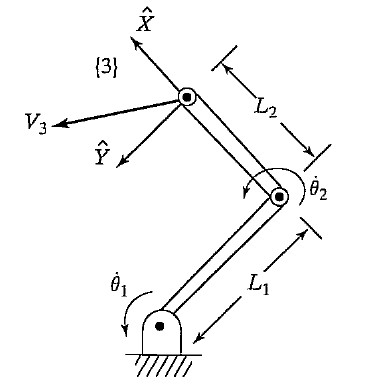

$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaamaabmaabaqbamqabiqaaaqa
% aiaadIhaaeaacaWG5baaaaGaayjkaiaawMcaaiabg2da9maabmaaba
% qbamqabiqaaaqaaiaadYeadaWgaaWcbaGaaGymaaqabaGccaWGJbWa
% aSraaSqaaiaaigdaaeqaaOGaey4kaSIaamitamaaBaaaleaacaaIYa
% aabeaakiaadogadaWgbaWcbaGaaGymaiaaikdaaeqaaaGcbaGaamit
% amaaBaaaleaacaaIXaaabeaakiaadohadaWgbaWcbaGaaGymaaqaba
% GccqGHRaWkcaWGmbWaaSbaaSqaaiaaikdaaeqaaOGaam4CamaaBeaa
% leaacaaIXaGaaGOmaaqabaaaaaGccaGLOaGaayzkaaaaaa!5491!
\[\left( {\begin{array}{*{20}{c}}
  x \\ 
  y 
\end{array}} \right) = \left( {\begin{array}{*{20}{c}}
  {{L_1}c{}_1 + {L_2}c{}_{12}} \\ 
  {{L_1}s{}_1 + {L_2}s{}_{12}} 
\end{array}} \right)\]$;$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaamaaCeaaleqabaGaaGimaaaa
% kiaadQeacaGGOaGaeqiUdeNaaiykaiabg2da9maabmaabaqbamqabi
% GaaaqaaiabgkHiTiaadYeadaWgaaWcbaGaaGymaaqabaGccaWGZbWa
% aSraaSqaaiaaigdaaeqaaOGaeyOeI0IaamitamaaBaaaleaacaaIYa
% aabeaakiaadohadaWgbaWcbaGaaGymaiaaikdaaeqaaaGcbaGaeyOe
% I0IaamitamaaBaaaleaacaaIYaaabeaakiaadohadaWgaaWcbaGaaG
% ymaiaaikdaaeqaaaGcbaGaamitamaaBaaaleaacaaIXaaabeaakiaa
% dogadaWgbaWcbaGaaGymaaqabaGccqGHRaWkcaWGmbWaaSbaaSqaai
% aaikdaaeqaaOGaam4yamaaBeaaleaacaaIXaGaaGOmaaqabaaakeaa
% caWGmbWaaSbaaSqaaiaaikdaaeqaaOGaam4yamaaBaaaleaacaaIXa
% GaaGOmaaqabaaaaaGccaGLOaGaayzkaaWaaSbaaSqaaiaadogadaWg
% aaadbaGaaGymaiaaikdaaeqaaSGaeyypa0Jaam4yamaaBaaameaaca
% aIXaaabeaaliaadogadaWgaaadbaGaaGOmaaqabaWccqGHsislcaWG
% ZbWaaSbaaWqaaiaaigdaaeqaaSGaam4CamaaBaaameaacaaIYaaabe
% aaliaacUdacaWGZbWaaSbaaWqaaiaaigdacaaIYaaabeaaliabg2da
% 9iaadogadaWgaaadbaGaaGymaaqabaWccaWGZbWaaSbaaWqaaiaaik
% daaeqaaSGaey4kaSIaam4CamaaBaaameaacaaIXaaabeaaliaadoga
% daWgaaadbaGaaGOmaaqabaaaleqaaaaa!7996!
\[{}^0J(\theta ) = {\left( {\begin{array}{*{20}{c}}
  { - {L_1}s{}_1 - {L_2}s{}_{12}}&{ - {L_2}{s_{12}}} \\ 
  {{L_1}c{}_1 + {L_2}c{}_{12}}&{{L_2}{c_{12}}} 
\end{array}} \right)_{{c_{12}} = {c_1}{c_2} - {s_1}{s_2};{s_{12}} = {c_1}{s_2} + {s_1}{c_2}}}\]$

A solution exist if $% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaamaaCeaaleqabaGaaGimaaaa
% kiaadQeadaahaaWcbeqaaiabgkHiTiaaigdaaaGccaGGOaGaeqiUde
% Naaiykaaaa!4341!
\[{}^0{J^{ - 1}}(\theta )\]$is posible, so a singularity exist when:$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaaiGacsgacaGGLbGaaiiDamaa
% dmaabaWaaWraaSqabeaacaaIWaaaaOGaamOsaiaacIcacqaH4oqCca
% GGPaaacaGLBbGaayzxaaGaeyypa0JaamitamaaBaaaleaacaaIXaaa
% beaakiaadYeadaWgaaWcbaGaaGOmaaqabaGccaWGZbWaaSraaSqaai
% aaikdaaeqaaOGaeyypa0JaaGimaaaa!4E55!
\[\det \left[ {{}^0J(\theta )} \right] = {L_1}{L_2}s{}_2 = 0\]$;

Clearly, a singularity of the mechanism exists when $\theta_2$ is 0 or 180 degrees. Physically, when $\theta_2 =0$ , the arm is stretched straight out. In this configuration, motion of the end-effector is possible along only one Cartesian direction (the one perpendicular to the arm). Therefore, the mechanism has lost one degree of freedom. Likewise, when $\theta_2 =180$, the arm is folded completely back on itself, and motion of the hand again is possible only in one Cartesian direction instead of two.

Consider the two-link robot is moving its end-effector along the X axis at 1.0 m/s. Show that joint rates are reasonable when far from a singularity, but that, as a singularity is approached at $\theta_2 =0$, joint rates tend to infinity.

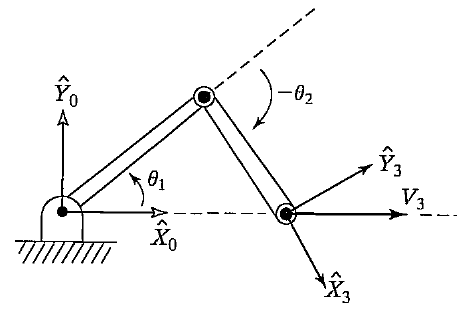

We start by calculating the inverse of the Jacobian written in {0}:


$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaamaaCeaaleqabaGaaGimaaaa
% kiaadQeadaahaaWcbeqaaiabgkHiTiaaigdaaaGccaGGOaGaeqiUde
% Naaiykaiabg2da9maalaaabaGaaGymaaqaaiaadYeadaWgaaWcbaGa
% aGymaaqabaGccaWGmbWaaSbaaSqaaiaaikdaaeqaaOGaam4CamaaBa
% aaleaacaaIYaaabeaaaaGcdaWadaqaauaadeqaciaaaeaacaWGmbWa
% aSbaaSqaaiaaikdaaeqaaOGaam4yamaaBaaaleaacaaIXaGaaGOmaa
% qabaaakeaacaWGmbWaaSbaaSqaaiaaikdaaeqaaOGaam4CamaaBaaa
% leaacaaIXaGaaGOmaaqabaaakeaacqGHsislcaWGmbWaaSbaaSqaai
% aaigdaaeqaaOGaam4yamaaBeaaleaacaaIXaaabeaakiabgkHiTiaa
% dYeadaWgaaWcbaGaaGOmaaqabaGccaWGJbWaaSraaSqaaiaaigdaca
% aIYaaabeaaaOqaaiabgkHiTiaadYeadaWgaaWcbaGaaGymaaqabaGc
% caWGZbWaaSraaSqaaiaaigdaaeqaaOGaeyOeI0IaamitamaaBaaale
% aacaaIYaaabeaakiaadohadaWgbaWcbaGaaGymaiaaikdaaeqaaaaa
% aOGaay5waiaaw2faaaaa!6903!
\[{}^0{J^{ - 1}}(\theta ) = \frac{1}{{{L_1}{L_2}{s_2}}}\left[ {\begin{array}{*{20}{c}}
  {{L_2}{c_{12}}}&{{L_2}{s_{12}}} \\ 
  { - {L_1}c{}_1 - {L_2}c{}_{12}}&{ - {L_1}s{}_1 - {L_2}s{}_{12}} 
\end{array}} \right]\]$$



$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaamaabmaabaqbamqabiqaaaqa
% aiqbeI7aXzaacaWaaSbaaSqaaiaaigdaaeqaaaGcbaGafqiUdeNbai
% aadaWgaaWcbaGaaGOmaaqabaaaaaGccaGLOaGaayzkaaGaeyypa0Ja
% amOsamaaCaaaleqabaGaeyOeI0IaaGymaaaakiaacIcacqaH4oqCca
% GGPaWaaeWaaeaafaWabeGabaaabaGaaGymaaqaaiaaicdaaaaacaGL
% OaGaayzkaaGaeyypa0ZaaeWaaeaafaWabeGabaaabaWaaSaaaeaaca
% WGJbWaaSbaaSqaaiaaigdacaaIYaaabeaaaOqaaiaadYeadaWgaaWc
% baGaaGymaaqabaGccaWGZbWaaSbaaSqaaiaaikdaaeqaaaaaaOqaam
% aalaaabaGaeyOeI0IaamitamaaBaaaleaacaaIXaaabeaakiaadoga
% daWgbaWcbaGaaGymaaqabaGccqGHsislcaWGmbWaaSbaaSqaaiaaik
% daaeqaaOGaam4yamaaBeaaleaacaaIXaGaaGOmaaqabaaakeaacaWG
% mbWaaSbaaSqaaiaaigdaaeqaaOGaamitamaaBaaaleaacaaIYaaabe
% aakiaadohadaWgaaWcbaGaaGOmaaqabaaaaaaaaOGaayjkaiaawMca
% aiabg2da9maabmaabaqbamqabiqaaaqaamaalaaabaGaam4yamaaBa
% aaleaacaaIXaGaaGOmaaqabaaakeaacaWGmbWaaSbaaSqaaiaaigda
% aeqaaOGaam4CamaaBaaaleaacaaIYaaabeaaaaaakeaacqGHsislda
% WcaaqaaiaadogadaWgbaWcbaGaaGymaaqabaaakeaacaWGmbWaaSba
% aSqaaiaaikdaaeqaaOGaam4CamaaBaaaleaacaaIYaaabeaaaaGccq
% GHsisldaWcaaqaaiaadogadaWgbaWcbaGaaGymaiaaikdaaeqaaaGc
% baGaamitamaaBaaaleaacaaIXaaabeaakiaadohadaWgaaWcbaGaaG
% OmaaqabaaaaaaaaOGaayjkaiaawMcaaaaa!7C4A!
\[\left( {\begin{array}{*{20}{c}}
  {{{\dot \theta }_1}} \\ 
  {{{\dot \theta }_2}} 
\end{array}} \right) = {J^{ - 1}}(\theta )\left( {\begin{array}{*{20}{c}}
  1 \\ 
  0 
\end{array}} \right) = \left( {\begin{array}{*{20}{c}}
  {\frac{{{c_{12}}}}{{{L_1}{s_2}}}} \\ 
  {\frac{{ - {L_1}c{}_1 - {L_2}c{}_{12}}}{{{L_1}{L_2}{s_2}}}} 
\end{array}} \right) = \left( {\begin{array}{*{20}{c}}
  {\frac{{{c_{12}}}}{{{L_1}{s_2}}}} \\ 
  { - \frac{{c{}_1}}{{{L_2}{s_2}}} - \frac{{c{}_{12}}}{{{L_1}{s_2}}}} 
\end{array}} \right)\]$$


Clearly, as the arm stretches out toward $\theta_2 =0$, both joint rates go to infinity.

### Trajectory with singularity

clear
mdl_twolink
twolink.plot(qz)
P1=[0.1 0 0]

P1 =     0.1000         0         0


P2=[1.99 0 0]

P2 =     1.9900         0         0


T1=transl(P1)

T1 =     1.0000         0         0    0.1000
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


T2=transl(P2)

T2 =     1.0000         0         0    1.9900
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


qu=twolink.ikine(T1,'mask',[1 1 0 0 0 0 ], 'q0',[pi/4 0])

qu =     1.5208   -3.0416


twolink.plot(qu,'zoom',2)
hold on
line([P1(1) P2(1)],[P1(2) P2(2)], [P1(3) P2(3)])
ts=0.05

ts = 0.0500

tf=2

tf = 2

t=(0:ts:tf)'

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


Trajec=ctraj(T1,T2,40);
qs_u=twolink.ikine(Trajec,'mask',[1 1 0 0 0 0 ], 'q0',[pi/2 0])

qs_u =     1.5208   -3.0416
    1.5194   -3.0388
    1.5152   -3.0304
    1.5082   -3.0163
    1.4984   -2.9967
    1.4857   -2.9715
    1.4703   -2.9406
    1.4520   -2.9040
    1.4309   -2.8617
    1.4068   -2.8137


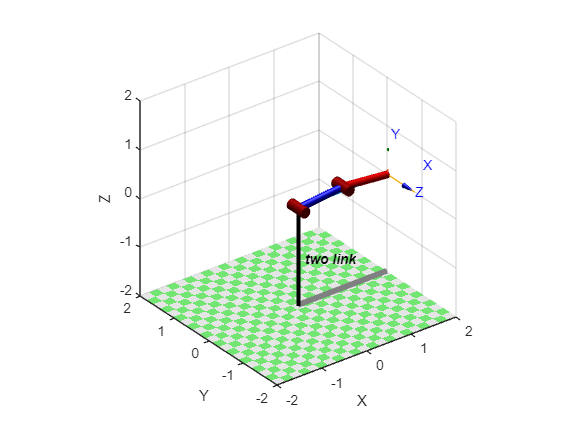

twolink.plot(qs_u, 'zoom',2, 'workspace',[-0.5 3 -0.5 0.5 -0.5 2])

### Joint velocities

See function below

[q1_d,q2_d] = th_dot(qs_u(:,1),qs_u(:,2))

q1_d =    -0.5006   -0.5007   -0.5008   -0.5010   -0.5013   -0.5018   -0.5025   -0.5035   -0.5049   -0.5068   -0.5093   -0.5125   -0.5166   -0.5218   -0.5282   -0.5357   -0.5443   -0.5543   -0.5658   -0.5790   -0.5944   -0.6122   -0.6331   -0.6577   -0.6872   -0.7231   -0.7676   -0.8219   -0.8867   -0.9647   -1.0600   -1.1785   -1.3288   -1.5243   -1.7868   -2.1520   -2.6782   -3.4445   -4.4272   -5.0063


q2_d =     1.0013    1.0013    1.0015    1.0020    1.0026    1.0036    1.0051    1.0071    1.0099    1.0136    1.0185    1.0249    1.0332    1.0437    1.0565    1.0714    1.0887    1.1086    1.1316    1.1581    1.1887    1.2244    1.2661    1.3155    1.3745    1.4462    1.5352    1.6439    1.7734    1.9294    2.1201    2.3570    2.6575    3.0487    3.5737    4.3039    5.3564    6.8890    8.8544   10.0125


### Plotting results: Time vs theta_dot's

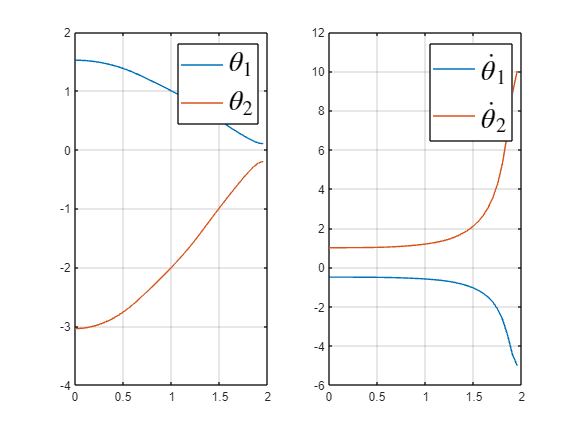

figure
subplot(121)
plot(t(1:40),qs_u(:,1),t(1:40), qs_u(:,2))
legend ('$\theta_1$','$\theta_2$','Interpreter','latex','Fontsize',20)
grid on
subplot(122)
plot(t(1:40),q1_d,t(1:40), q2_d)
legend('${{\dot \theta }_1}$','${{\dot \theta }_2}$','Interpreter','latex','Fontsize',20)
grid on

### Plotting results: Theta_2 vs theta_dot's

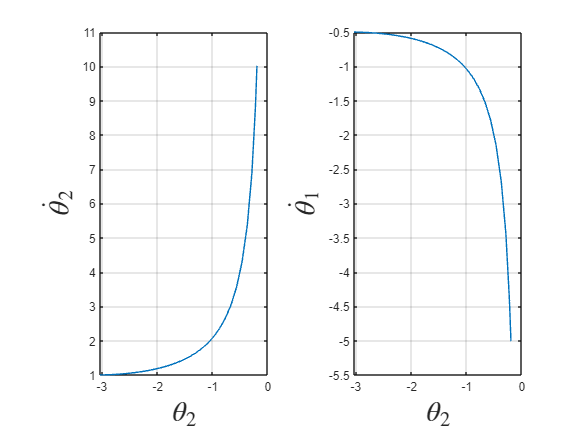

figure
subplot(121)
plot(qs_u(:,2), q2_d)
xlabel ('$\theta_2$','Interpreter','latex','Fontsize',20)
ylabel('${{\dot \theta }_2}$','Interpreter','latex','Fontsize',20)
grid on
subplot(122)
plot(qs_u(:,2), q1_d)
xlabel ('$\theta_2$','Interpreter','latex','Fontsize',20)
ylabel('${{\dot \theta }_1}$','Interpreter','latex','Fontsize',20)
grid on

## Manipulability-Twolink

### Sphere equation

syms x y z real
[x y z]*[x y z]'

$$ans = x^{2}+y^{2}+z^{2}$$

Consider the set of generalized joint velocities with a unit norm which lie on the surface of a hypersphere in the N-dimensional joint velocity space.


$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaaiqbfI5arzaacaGaeyypa0Ja
% amOsamaaCaaaleqabaGaeyOeI0IaaGymaaaakiaacIcacqqHyoquca
% GGPaGabmiwayaacaaaaa!457C!
\[\dot \Theta  = {J^{ - 1}}(\Theta )\dot X\]$$



$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaaiqbfI5arzaacaWaaWbaaSqa
% beaacaWGubaaaOGafuiMdeLbaiaacqGH9aqpcaaIXaaaaa!4263!
\[{{\dot \Theta }^T}\dot \Theta  = 1\]$$



$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaaiqbfI5arzaacaWaaWbaaSqa
% beaacaWGubaaaOGafuiMdeLbaiaacqGH9aqpcaaIXaGaeyOKH46aae
% WaaeaacaWGkbWaaWbaaSqabeaacqGHsislcaaIXaaaaOGaaiikaiab
% fI5arjaacMcaceWGybGbaiaaaiaawIcacaGLPaaadaahaaWcbeqaai
% aadsfaaaGccaWGkbWaaWbaaSqabeaacqGHsislcaaIXaaaaOGaaiik
% aiabfI5arjaacMcaceWGybGbaiaacqGH9aqpceWGybGbaiaadaahaa
% WcbeqaaiaadsfaaaGcdaqadaqaaiaadQeacaGGOaGaeuiMdeLaaiyk
% aiaadQeadaahaaWcbeqaaiaadsfaaaGccaGGOaGaeuiMdeLaaiykaa
% GaayjkaiaawMcaamaaCaaaleqabaGaeyOeI0IaaGymaaaakiabg2da
% 9iaaigdaaaa!6424!
\[{{\dot \Theta }^T}\dot \Theta  = 1 \to {\left( {{J^{ - 1}}(\Theta )\dot X} \right)^T}{J^{ - 1}}(\Theta )\dot X = {{\dot X}^T}{\left( {J(\Theta ){J^T}(\Theta )} \right)^{ - 1}} = 1\]$$


Which is the equation of points on the surface of an ellipsoid within the dim T-dimensional end-effector velocity space. If this ellipsoid is close to spherical, that is, its radii are of the same order of magnitude then all is well – the end-effector can achieve arbitrary Cartesian velocity. However if one or more radii are very small this indicates that the endeffector cannot achieve velocity in the directions corresponding to those small radii.

clear
clc
clf
mdl_planar2
q=[30*pi/180 40*pi/180]

q =     0.5236    0.6981


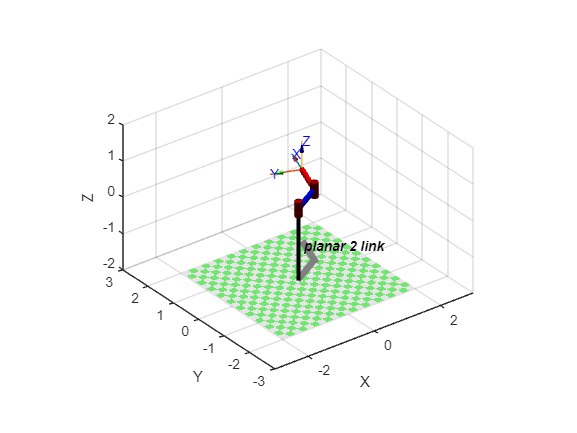

p2.plot(q)
axis([-3 3 -3 3 -2 2])
hold on

### Plotting the ellipses 

#### Case 1

q=[30*pi/180 40*pi/180]

q =     0.5236    0.6981


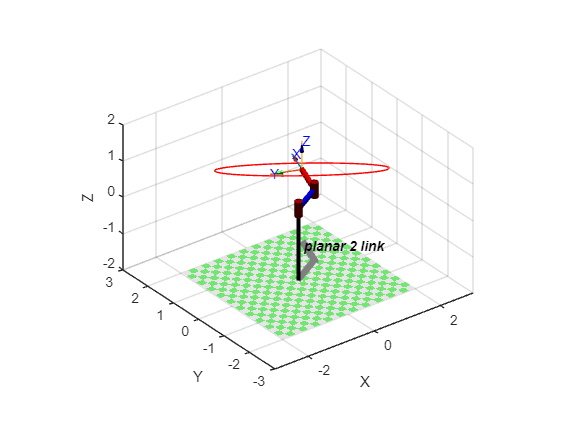

J = p2.jacob0(q);
J = J(1:2,1:2);
N = (J*J');
t = transl(p2.fkine(q));
plot_ellipse(N, t(1:2))
p2.vellipse(q,'2d')

#### Case 2

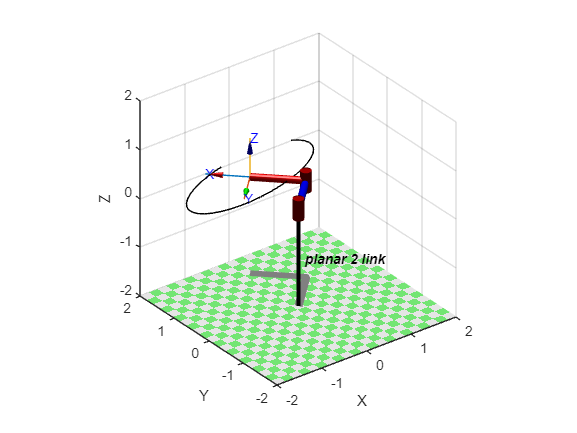

q=[45*pi/180 90*pi/180];
J = p2.jacob0(q);
J = J(1:2,1:2);
N = (J*J');
clf
axis([-3 3 -3 3 -2 2])
p2.plot(q)
hold on
t= transl(p2.fkine(q));
plot_ellipse(N, t(1:2))

#### Case near singularity

q=[45*pi/180 10*pi/180]

q =     0.7854    0.1745


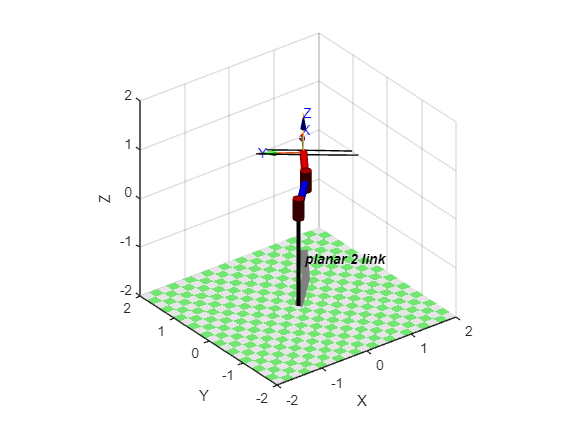

J = p2.jacob0(q);
J = J(1:2,1:2);
N = (J*J');
clf
axis([-3 3 -3 3 -2 2])
p2.plot(q)
hold on
t= transl(p2.fkine(q));
plot_ellipse(N, t(1:2))

## Playing with the Puma

Jacobian for the ready pose 

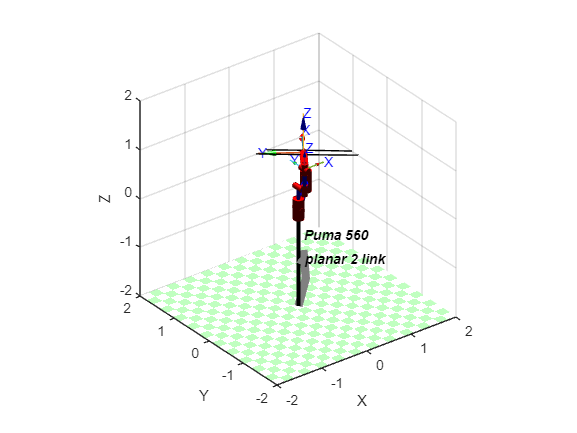

clear
mdl_puma560
p560.plot(qr)

J = p560.jacob0(qr)% see the dimension

J =     0.1500   -0.8636   -0.4318         0         0         0
    0.0203    0.0000    0.0000         0         0         0
         0    0.0203    0.0203         0         0         0
         0         0         0         0         0         0
         0   -1.0000   -1.0000         0   -1.0000         0
    1.0000    0.0000    0.0000    1.0000    0.0000    1.0000


Det_te=det(J)

Det_te = 0

Rango=rank(J)

Rango = 5

jsingu(J)

1 linearly dependent joints:
  q6 depends on: q4 


qd = (inv(J)*[0 0 0.1 0 0 0]')'

qd =    NaN   NaN   NaN   NaN   NaN   NaN


Jacobian near a singularity

qns = qr; qns(5) = 5*pi/180

qns =          0    1.5708   -1.5708         0    0.0873         0


J=p560.jacob0(qns)

J =     0.1500   -0.8636   -0.4318         0         0         0
    0.0203    0.0000    0.0000         0         0         0
   -0.0000    0.0203    0.0203         0         0         0
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0872
    0.0000   -1.0000   -1.0000    0.0000   -1.0000   -0.0000
    1.0000    0.0000    0.0000    1.0000    0.0000    0.9962


Det_te=det(J)

Det_te = -1.5509e-05

Rango=rank(J)

Rango = 6

qd_t = (inv(J)*[0 0 0.1 0 0 0]')'

qd_t =    -0.0000   -4.9261    9.8522    0.0000   -4.9261         0


qd_r = (inv(J)*[0 0 0 0 0.2 0]')'

qd_r =     0.0000    0.0000   -0.0000    0.0000   -0.2000   -0.0000


Plotting ellipses

mdl_puma560
qns = qr; 
qns(5) = 5 * pi/180

qns =          0    1.5708   -1.5708         0    0.0873         0


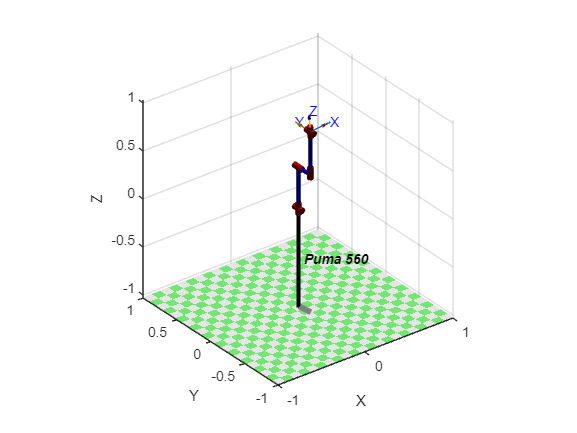

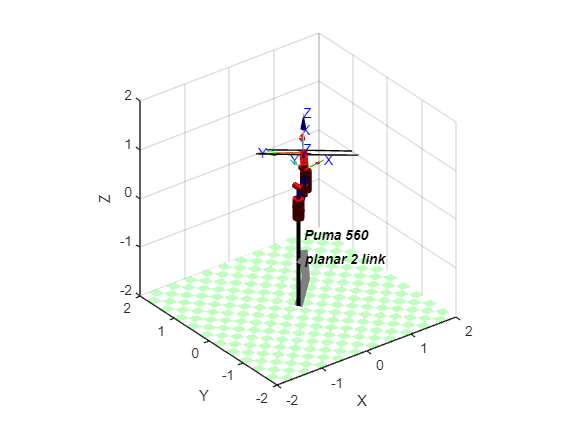

figure
p560.plot(qns,'zoom',2)

Translational ellipse

J0= p560.jacob0(qns)

J0 =     0.1500   -0.8636   -0.4318         0         0         0
    0.0203    0.0000    0.0000         0         0         0
   -0.0000    0.0203    0.0203         0         0         0
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0872
    0.0000   -1.0000   -1.0000    0.0000   -1.0000   -0.0000
    1.0000    0.0000    0.0000    1.0000    0.0000    0.9962


J = J0(1:3,:)

J =     0.1500   -0.8636   -0.4318         0         0         0
    0.0203    0.0000    0.0000         0         0         0
   -0.0000    0.0203    0.0203         0         0         0


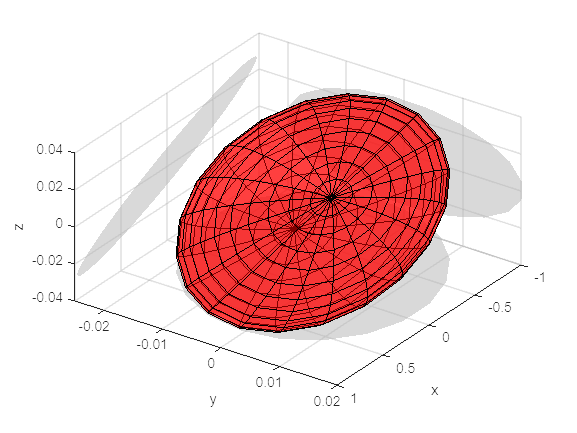

figure
plot_ellipse(J*J','fillcolor','r','alpha',0.5,'shadow');
view (125,45)
%axis([-1 1 -1 1 -1 1])
xyzlabel
grid on

Rotational ellipse

J0= p560.jacob0(qns)

J0 =     0.1500   -0.8636   -0.4318         0         0         0
    0.0203    0.0000    0.0000         0         0         0
   -0.0000    0.0203    0.0203         0         0         0
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0872
    0.0000   -1.0000   -1.0000    0.0000   -1.0000   -0.0000
    1.0000    0.0000    0.0000    1.0000    0.0000    0.9962


J = J0(4:6,:)

J =    -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0872
    0.0000   -1.0000   -1.0000    0.0000   -1.0000   -0.0000
    1.0000    0.0000    0.0000    1.0000    0.0000    0.9962


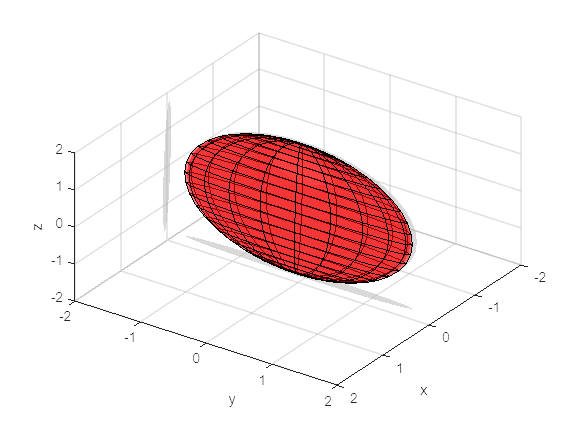

figure
plot_ellipse(J*J','fillcolor','r','alpha',0.5,'shadow');
view (125,45)
axis([-2 2 -2 2 -2 2])
xyzlabel
grid on

Manipulability

$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaaiaad2gacqGH9aqpdaGcaaqa
% aiGacsgacaGGLbGaaiiDaiaacIcacaWGkbGaamOsamaaCaaaleqaba
% GaamivaaaakiaacMcaaSqabaaaaa!4577!
\[m = \sqrt {\det (J{J^T})} \]$;Yoshikawa’s manipulability measure


m = p560.maniplty(qr)

m = 0


mn=p560.maniplty(qn)

mn = 0.0786

## Functions


$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuWqOfgBRj2BHjhzae
% rbuLwBLnhis9wBH5garuavP1wzZbss0fgBPngarmWu51MyVXgaruav
% P1wzZbIqVXgzaerbd9wDYLwzYbqee0evGueE0jxyaibaieYlf9irVe
% eu0dXdh9vqqj-hHeeu0xXdbba9frFj0-OqFfea0dXdd9vqaq-JfrVk
% FHe9pgea0dXdar-Jb9hs0dXdbPYxe9vr0-vr0-vqpi0dc9GqpWqaai
% aadiabcqaaeaqbbiaagaGaaCaaaOqaamaabmaabaqbamqabiqaaaqa
% aiqbeI7aXzaacaWaaSbaaSqaaiaaigdaaeqaaaGcbaGafqiUdeNbai
% aadaWgaaWcbaGaaGOmaaqabaaaaaGccaGLOaGaayzkaaGaeyypa0Ja
% amOsamaaCaaaleqabaGaeyOeI0IaaGymaaaakiaacIcacqaH4oqCca
% GGPaWaaeWaaeaafaWabeGabaaabaGaaGymaaqaaiaaicdaaaaacaGL
% OaGaayzkaaGaeyypa0ZaaeWaaeaafaWabeGabaaabaWaaSaaaeaaca
% WGJbWaaSbaaSqaaiaaigdacaaIYaaabeaaaOqaaiaadYeadaWgaaWc
% baGaaGymaaqabaGccaWGZbWaaSbaaSqaaiaaikdaaeqaaaaaaOqaam
% aalaaabaGaeyOeI0IaamitamaaBaaaleaacaaIXaaabeaakiaadoga
% daWgbaWcbaGaaGymaaqabaGccqGHsislcaWGmbWaaSbaaSqaaiaaik
% daaeqaaOGaam4yamaaBeaaleaacaaIXaGaaGOmaaqabaaakeaacaWG
% mbWaaSbaaSqaaiaaigdaaeqaaOGaamitamaaBaaaleaacaaIYaaabe
% aakiaadohadaWgaaWcbaGaaGOmaaqabaaaaaaaaOGaayjkaiaawMca
% aiabg2da9maabmaabaqbamqabiqaaaqaamaalaaabaGaam4yamaaBa
% aaleaacaaIXaGaaGOmaaqabaaakeaacaWGmbWaaSbaaSqaaiaaigda
% aeqaaOGaam4CamaaBaaaleaacaaIYaaabeaaaaaakeaacqGHsislda
% WcaaqaaiaadogadaWgbaWcbaGaaGymaaqabaaakeaacaWGmbWaaSba
% aSqaaiaaikdaaeqaaOGaam4CamaaBaaaleaacaaIYaaabeaaaaGccq
% GHsisldaWcaaqaaiaadogadaWgbaWcbaGaaGymaiaaikdaaeqaaaGc
% baGaamitamaaBaaaleaacaaIXaaabeaakiaadohadaWgaaWcbaGaaG
% OmaaqabaaaaaaaaOGaayjkaiaawMcaaaaa!7C4A!
\[\left( {\begin{array}{*{20}{c}}
  {{{\dot \theta }_1}} \\ 
  {{{\dot \theta }_2}} 
\end{array}} \right) = {J^{ - 1}}(\theta )\left( {\begin{array}{*{20}{c}}
  1 \\ 
  0 
\end{array}} \right) = \left( {\begin{array}{*{20}{c}}
  {\frac{{{c_{12}}}}{{{L_1}{s_2}}}} \\ 
  {\frac{{ - {L_1}c{}_1 - {L_2}c{}_{12}}}{{{L_1}{L_2}{s_2}}}} 
\end{array}} \right) = \left( {\begin{array}{*{20}{c}}
  {\frac{{{c_{12}}}}{{{L_1}{s_2}}}} \\ 
  { - \frac{{c{}_1}}{{{L_2}{s_2}}} - \frac{{c{}_{12}}}{{{L_1}{s_2}}}} 
\end{array}} \right)\]$$



$$L_1 =L_2 =1$$


function [q1_d,q2_d] = th_dot(th_1,th_2)
for i=1:length(th_1)
c12=cos(th_1(i)+th_2(i));
s2=sin(th_2(i));
c1=cos(th_1(i));
q1_d(i)=c12/s2;
q2_d(i)=-(c1+c12)/s2;
end
end